# Structure Preserving Model Order Reduction by Parameter Optimization (SOBMOR)

## Introduction

One important goal in model order reduction is the development of ROMs with high accuracies measured in certain system norms. Comparing structure preserving methods with their non structure-preserving counterparts shows that structure preservation often comes with deterioration of approximation quality. SOBMOR, introduced in [1], is a $\mathcal{H}_\infty$-inspired MOR method based on parameter optimization that encods structural constraints in the parameterization of the ROM. The method only needs transfer function evaluations of the original model and can thus be applied to a variety of dynamical systems. 

### The idea

We consider a parameter vector $\theta \in \mathbb{R}^{n_\theta}$ with $n_\theta = n_x\bigg(\frac{3n_x+1}{2}+n_u\bigg)$. This parameter vectors is partitioned as $\theta := [\theta_J^\mathbf{T},\theta_R^\mathbf{T},\theta_Q^\mathbf{T},\theta_G^\mathbf{T}]^\mathbf{T}$ with $\theta_J \in \mathbb{R}^{n_x(n_x-1)/2}$, $\theta_R, \theta_Q \in \mathbb{R}^{n_x(n_x+1)/2}$ and $\theta_G \in \mathbb{R}^{n_x\cdot n_u}$. With this the system matrices $\mathbf{J}(\theta), \mathbf{R}(\theta), \mathbf{Q}(\theta), \mathbf{G}(\theta)$can be constructed according to Lemma 3.1 in [1] and we can assign a pH system to each $\theta \in \mathbb{R}^{n_\theta}$.

The direct minimization of the $\mathcal{H}_\infty$-norm with respect to $\theta$ comes with several problems. The computation of the $\mathcal{H}_\infty$-norm is computationally expensive, faster methods typically only calculate an approximation of the norm. Moreover, the optimization problem is nonlinear, nonsmooth and nonconvex. To circumvent these problems a leveled-least-squares approach is applied:

Let $S := \{s_j\}_{j=1}^{n_s} \subset \text{i}\mathbb{R}$ denote a set of $n_s$ sample points and let $\sigma_k(\cdot)$ denote the $k$-th singular value of a matrix. We minimize

$L(\gamma,\mathbf{G},\hat{\mathbf{G}}(\cdot,\theta),S) := \frac{1}{\gamma}\sum\limits_{s_j \in S} \Bigg( \sum \limits_{k=1}^{m} \bigg(  \big[\sigma_k \big( \mathbf{G}(s_j) - \hat{\mathbf{G}}(s_j,\theta) \big) - \gamma \big]_+ \bigg)^2 \Bigg)$    (1)

with respect to $\theta$, where


$$[\cdot]_+ : \mathbb{R} \to \overline{\mathbb{R}^+}, x \mapsto \begin{cases}
		x & \text{if } x\ge 0,\\
		0 & \text{if } x<0
	\end{cases}$$


for decreasing values $\gamma > 0$.

Minimizing $L$ instead of the $\mathcal{H}_\infty$-error is computational less demanding since $\mathbf{G}$ has to be evaluated only once at S in the beginning of the optimization step. Remaining computations only involve the ROM. Additionally, L depends smoothly on $\theta$ enabling gradient based optimization. The value $\gamma$ plays a curcial role in the minimization of (1). It is updated either according to a fixed sequence or by a bisection algorithm.

The method consists of 3 main steps: initialization, $\gamma$-selection and optimization, from which the last two are repeated iteratively.

#### Initialization

Initialization is either done by an interpolatory method or a random model that meets the structural constraints. In our code we supply IRKA-PH and CIRKA-PH as possible choices.

#### $\gamma$-selection

After the optimization of $L$, $\gamma$ is increased, descreased or the method stops, depending of the final value of $L$. As mentioned before the selection of $\gamma$ can either be done by a prescribed sequence or a bisection algorithm. In case of the former $\gamma$ is only decreased or the method stops. In case of the latter $\gamma$ is always inbetween to boarders that are adapted according to the optimization.

#### Optimization

For optimization we apply the third party software Granso. The algorithm implemented in *granso* is a sequential quadratic method utilizing Broyden-Fletcher-Goldfarb-Shanno quasi-Newton Hessian approximations for solving nonsmooth and nonconvex optimization problems. If after the optimization $L$ is greater than a tolerance $\epsilon$ the method stops, otherwise the optimization is carried out again with a new $\gamma$ and initialized with the parameter vector $\theta$ obtained from the prior optimization.

#### Initialization and adaption of $S$

The set of sample points $S$ can be fixed or adapted dynamically. For the latter one, a reasonable initialization is necessary. One way to do so is a greedy strategy introduced in [2]. Since this requires repeated evaluations of the $\mathcal{H}_\infty$-norm and therefore is computationally demanding, we utilize the fact that we initially reduce the full order model with IRKA-PH. The eigenvalues of the model obtained from IRKA-PH will have eigenvalues close to the peaks of $\mathbf{G}(\text{i}\omega)$, which will in turn produce peaks in the transfer function of the ROM. Thus, we project these eigenvalues onto the imaginary axis to cover closer surroundings of local maxima of $\mathbf{G}(\text{i}\omega)$.

Instead of taking into account a large amount of sample points, we apply the logarithmic sampling adaption from [3]. The procedure automatically adds sample points to $S$ inbetween existing ones if necessary.

### Pseudo-Code ($\gamma$-sequence)

## Toolbox Implementation

The MORpH toolbox provides an implementation of the SOBMOR algorithm called *sobmor*.

It combines multiple subroutines such as *irkaPH*,* cirkaPH *and third-party software such as *granso, linorm_subsp, Manopt*.

For more information, refer to the documentation:

help sobmor

  sobmor - obtaining a H-inf-optimal reduced pH system via parameter optimization
  Syntax:
    sysr = sobmor(sys, q)
    sysr = sobmor(sys, q, options)
 
  Description:
        sysr = sobmor(sys,q, options) returns a reduced PH system with given order q
 
  Input Arguments:
        *Required Input Arguments:*
        - sys:          phs object
        - q:            desired reduced order
        *Optional Input Arguments:*
        - Opts:  structure with execution parameters
            - .maxIter                  Maximum number of iterations 
                                        (leveled least-squares: max iterates per loop)
                                        [{1e5} / positive integer]
            - .adaptiveSampling         Use logarithmic sampling adaption from [2]
                                        [{true} / false]
            - .samplePoints             Sample points used for optimization 
                                        if .adaptiveSampling

## Examples

### Ladder Network

The first example considered here is a SISO Ladder Network with an architecture as shown below:  

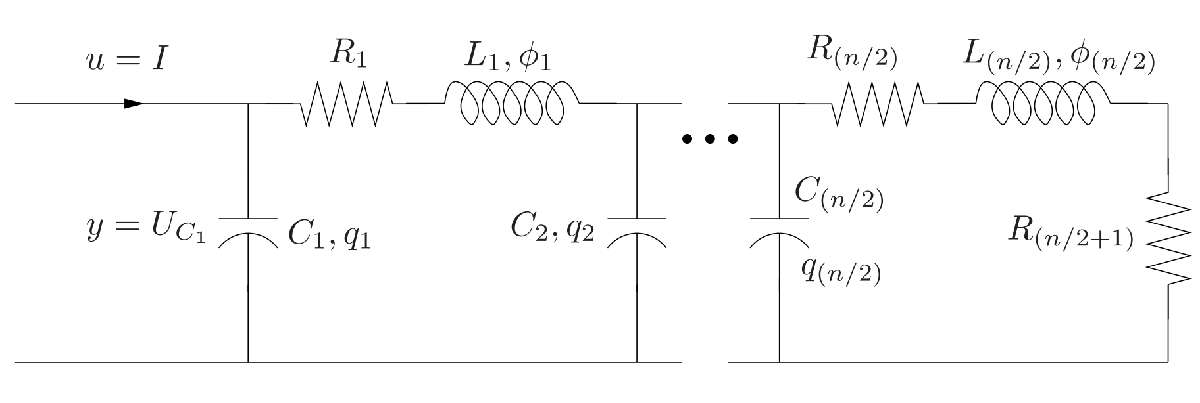

Image source: [4]

We consider a model with dimension $n = 100$, i.e. 50 inductances ($L_i = 0.1\text{H}$), 50 capacitors ($C_i = 0.1\text{F}$) and 51 resistances ($R_i=3\Omega$).

sys = setup_LadderNetworkSystem(100,0.1,0.1,3)

sys =   phs with properties:

               J: [100×100 double]
               R: [100×100 double]
               Q: [100×100 double]
               G: [100×1 double]
               E: [100×100 double]
               P: [100×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 100
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


*sobmor* in its simplest form is called by providing the system to reduce and the desired reduced order:

warning('off')
sysr = sobmor(sys, 10)

sysr =   phsRed with properties:

      parameters: [1×1 struct]
          method: @sobmor
            info: [1×1 struct]
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×1 double]
               E: [10×10 double]
               P: [10×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


norm(sys - sysr, inf)

ans = 0.0167

### Options

Since *sobmor* is such a high-level algorithm, it provides many (nested) options. The levels of options are:

- Top level (SOBMOR): e.g. initial guess for $\theta$, initial reduction strategy, maximum number of optimization steps

- Second level (*irkaPH, cirkaPH, granso*): e.g. convergence criteria of IRKA, maximum number of irkaPH iterations, optimization options

- Third level (*phs*): e.g. switching on/off input validation

You can find more information on the respective options by having a look at the documentation, e.g.

help irkaPH

  irkaPH - calculates the reduced order system redSys by application of the
           Iterative Rational Krylov Algorithm (IRKA algorithm) for PH
           systems [1]
 
  Syntax:
    redSys = irkaPH(sys, redOrder)
    redSys = irkaPH(sys, redOrder, Opts)
    redSys = irkaPH(sys, s0)
    redSys = irkaPH(sys, s0, Opts)
    redSys = irkaPH(sys, s0, b)
    redSys = irkaPH(sys, s0, b, Opts)
    [redSys, V, s0, b, W, nLU] = irkaPH(sys, redOrder, ...)
 
  Description:
        redSys = irkaPH(sys, redOrder) returns a reduced PH system of order
        redOrder.
 
        redSys = irkaPH(sys, s0) returns a reduced PH system
        where s0 is used as initial guess for the interpolation
        points.
 
        redSys = irkaPH(sys, s0, b) returns a reduced PH system
        where s0 and b are used as initia

To provide these options, use nested structs. As example, the following code changes the maximum number of iterations, the initial $\gamma_{max}$, give intermediate output, change the initial reduction method, etc.:

Opts = struct();
Opts.maxIter = 500;                 % Maximum number of iterations
Opts.gammaMax = 2;                  % Increase gamma_max
Opts.printLevel = 1;                % Define intermediate output
Opts.initialReduction = 'cirkaPH';  % Initial reduction method
Opts.selectionScheme = 'bisection'; % gamma selection scheme
Opts

Opts = struct with fields:
             maxIter: 500
            gammaMax: 2
          printLevel: 1
    initialReduction: 'cirkaPH'
     selectionScheme: 'bisection'


sysr = sobmor(sys,10,Opts)

Gamma: 1

###### QUADPROG NOTICE ####################################################################
#  GRANSO requires a quadratic program (QP) solver that has a quadprog-compatible         #
#  interface, as defined by MATLAB's own QP solver quadprog (available in the             #
#  Optimization Toolbox).  MOSEK also provides a quadprog-compatible interface to their   #
#  QP solver and, of course, one may always write a quadprog-compatible wrapper for the   #
#  QP solver of one's choice.                                                             #
#                                                                                         #
#  Note that GRANSO's performance, in terms of efficiency and/or optimization quality,    #
#  may vary depending upon which QP solver is employed, particularly for nonsmooth        #
#  constrained optimization problems.                                                     #
#                                                                     

sysr =   phsRed with properties:

      parameters: [1×1 struct]
          method: @sobmor
            info: [1×1 struct]
               J: [10×10 double]
               R: [10×10 double]
               Q: [10×10 double]
               G: [10×1 double]
               E: [10×10 double]
               P: [10×1 double]
               S: 0
               N: 0
            Opts: [1×1 struct]
             dim: 10
          isMIMO: 0
      isImplicit: 0
           isDAE: 0
    hasStaircase: 0


norm(sys - sysr, inf)

ans = 0.0168

### Output

*sobmor* providesonly the reduced order system and a struct as output. This redSys type contains additional information which makes the creation more transparent:

sysr.method         % Method with which the system was created (should be @sobmor)

ans = function_handle with value:
    @sobmor


sysr.parameters     % Execution parameters (options, sample points)

ans = struct with fields:
                   maxIter: 500
                  gammaMax: 2
                printLevel: 1
          initialReduction: 'cirkaPH'
           selectionScheme: 'bisection'
                   cirkaPH: [1×1 struct]
                    irkaPH: [1×1 struct]
                       phs: [1×1 struct]
          adaptiveSampling: 1
                      plot: 0
              tolBisection: 0.1000
            tolTermination: 1.0000e-14
                    tolLsa: 0.5000
                   adaptPH: [1×1 struct]
    additionalSamplePoints: [14×1 double]
              samplePoints: [807×1 double]
             gammaSequence: [100 94.1777 88.6943 83.5302 78.6668 74.0866 69.7730 65.7106 61.8847 58.2815 54.8882 51.6924 48.6827 45.8482 43.1788 40.6648 38.2971 36.0673 33.9674 31.9897 30.1271 28.3730 26.7211 25.1653 23.7001 22.3202 21.0206 19.7967 … ]
                    granso: [1×1 struct]
                   samples: {16×3 cell}


sysr.info           % Additional information, e.g. gamma

ans = struct with fields:
        time: 1.7016
        dims: [1×1 struct]
       gamma: 0.0176
    gammaMax: 0.0176
    gammaMin: 0.0156


Explanation of the info entries:

- *time*:    execution time

- *dims*:    relevant system dimensions

- *gamma*:    final value $\gamma$ (only leveled-least-squares approach)

- *gammaMax*:    final value $\gamma_{max}$ (only $\gamma$-Bisection)

- *gammaMin*:    final value $\gamma_{min}$ (only $\gamma$-Bisection)

## References

[1] P. Schwerdtner and M. Voigt. Structure Preserving Model Order Reduction by Parameter Optimization. arXiv Preprint arXiv:2011.07567. 2020. url: https://arxiv.org/abs/2011.07567.

[2] Beddig, Benner, Dorschky et. al., "Model Reduction for Second-Order Dynamical Systems Revisited", PAMM, vol. 19, 2019.

[3] P. Schwerdtner, M. Voigt. Adaptive Sampling for Structure Preserving Model Order Reduction of Port-Hamiltonian Systems.IFAC-PapersOnLine 54(19) (2021), pp. 143-148.

[4] R. V. Polyuga, "Model reduction of port-Hamiltonian systems", PhD thesis, University of Groningen, 2010.

## Copyright

This file is part of [MORpH](https://github.com/MORLab/MORpH) - a MATLAB toolbox to store, analyze, interconnect and reduce large-scale port-Hamiltonian models.

Authors: Maximilian Bonauer    |    E-Mail: [morlab.rt@ed.tum.de](mailto:morlab.rt@ed.tum.de)    |    Website: [www.epc.ed.tum.de/rt](https://www.epc.ed.tum.de/en/rt/home)  

© 2022 Chair of Automatic Control, TUM (see LICENSE.md)